## Load Data

clear
clf
clc

[train_images,test_images,train_labels,test_labels] = load_MNIST();

## PCA

all_images = [train_images test_images];

[train_pca,test_pca] = pcaManual(all_images,train_images,test_images)

train_pca =     1.3085    1.2055   -1.4755    2.4504   -2.7936   -0.8095    0.7037    1.2791    0.3990   -1.7495    2.6265    1.0234    3.3482   -0.5320    0.9875   -3.3295    0.0559    1.0686    0.8521   -0.2015   -1.9135    1.4456   -0.7047    2.1387    1.2128    4.1941   -1.5987    2.4926   -0.7359   -0.3950    0.2902    2.5745   -0.2674   -0.6245    1.0261    0.8494    1.0017    1.0307   -2.1986   -1.0599    1.4536    1.3830   -1.3069    0.0921    0.1788   -3.3221    0.3488    0.6750    0.2937    3.0229
    3.4705    6.9538    2.7597   -0.1343    1.4565    3.7204    0.1264    4.9655   -0.4386    1.7988    2.3994    0.5897    4.0481    3.9802   -0.4113    2.4258    3.3565    1.4820    2.1734   -0.0981    4.2999    7.0442    0.4421   -0.1707    1.9553    5.9931    0.5870    6.0396    4.3536    0.4470    1.8269    2.1310    2.9632    0.5774    5.4045    0.6420    3.2633    6.6861    1.6349    3.9990   -0.9179    2.3119    0.0237    0.3130    1.0360    1.9272    2.0687    1.9967    1.8

test_pca =    -2.8311    3.8353    1.7737   -0.3628   -2.7539    1.9940   -2.0968   -1.2786   -0.5182   -3.1922    2.4269    0.8164   -3.8221   -0.0858    1.6690    1.5966   -3.4246   -2.5411    1.4737   -2.5340   -1.6983    0.1614   -0.7544    0.5109   -1.8008    0.4450   -2.2405   -3.3991    1.4718    0.6931    1.1352    0.1357    1.3190   -0.9870   -0.9494    1.7154   -2.6281    0.6108    3.2219    2.2611    0.8219   -2.3046   -2.6708    1.5939    1.0738    1.6750    0.0649    0.0207   -3.9855   -2.8764
    1.6422    3.0915   -0.7185    7.8480    3.7038   -1.0153    1.9364    1.7228    4.0197    2.8513    7.3642    4.3016    2.2943    7.0815   -0.4575    3.3849    3.6247    2.8787    3.2808    2.0093    1.5377    3.6719    2.6332    2.7375    1.5811   10.4132    1.9318    3.8451    7.4085   -0.0216    2.2657    0.0253    2.6839    4.8421    1.8930    4.6224    2.3993   -0.4351    2.6254   -0.5766   -0.4215    1.3089    1.3397    1.0365    1.3181    3.3260    1.1537    1.1591    5.12

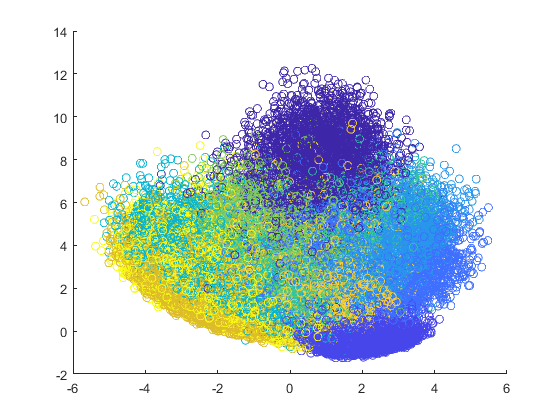


% Plot the data
scatter(train_pca(1,:),train_pca(2,:),[],train_labels)

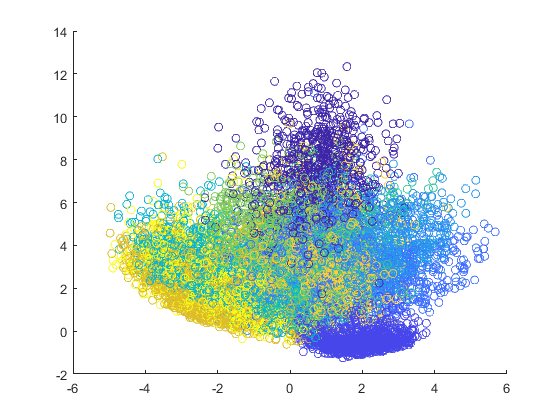

scatter(test_pca(1,:),test_pca(2,:)  ,[],test_labels)

## Nearest Class Centroid Classifier

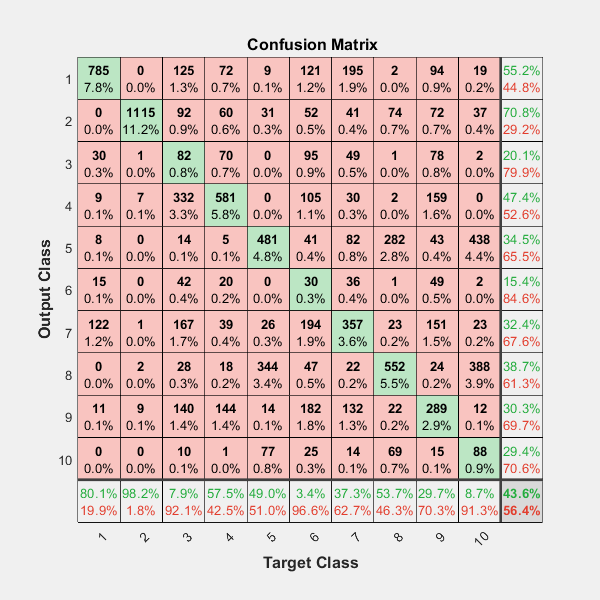

Overall precision: 43.6%


Elapsed time is 2.232273 seconds.


%PCA
class_labels = nearestClassCentroidClassifier(train_labels, train_pca, test_pca);
plotconfusionMatrixManualMNIST(test_pca, test_labels, class_labels)

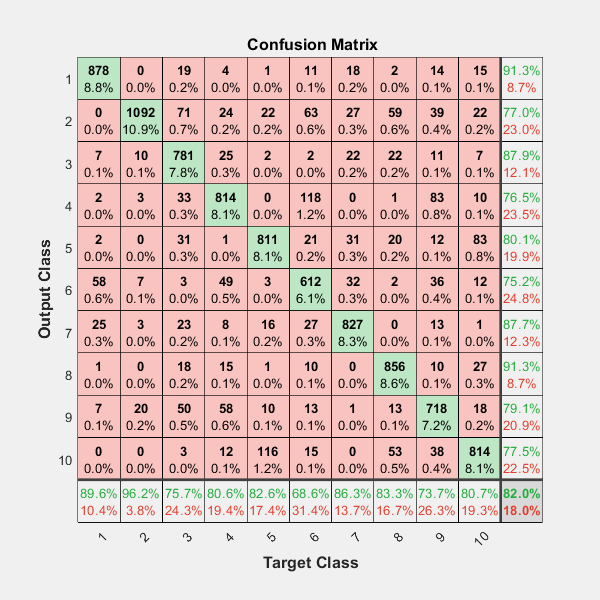

Overall precision: 82.03%


Elapsed time is 1.473488 seconds.


%Real Data
class_labels = nearestClassCentroidClassifier(train_labels, train_images, test_images);
plotconfusionMatrixManualMNIST(test_images, test_labels, class_labels)

## Nearest Sub-Class Centroid Classifier 2 PCA

%Pca
tic
class_labels = NearestSubClassCentroidClassifier(train_labels, train_pca, test_pca, 2);
plotconfusionMatrixManualMNIST(test_pca, test_labels, class_labels')

Overall precision: 42.86%


toc

Elapsed time is 2.737199 seconds.


## Nearest Sub-Class Centroid Classifier 2

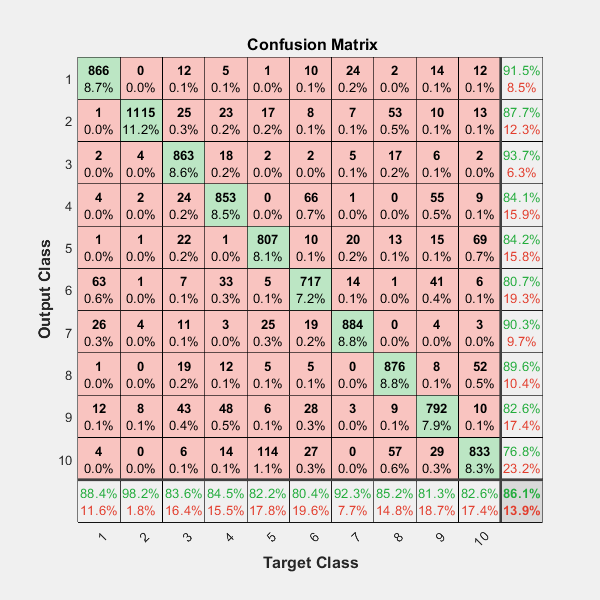

Overall precision: 86.06%


%Real Data
tic
class_labels = NearestSubClassCentroidClassifier(train_labels, train_images, test_images, 2);
plotconfusionMatrixManualMNIST(test_images, test_labels, class_labels')

toc

Elapsed time is 105.196861 seconds.


## Nearest Sub-Class Centroid Classifier 3 PCA

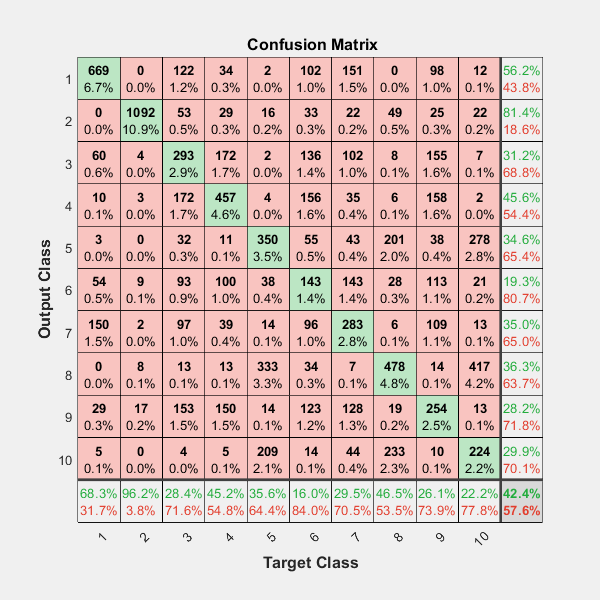

Overall precision: 42.43%


%Pca
class_labels = NearestSubClassCentroidClassifier(train_labels, train_pca, test_pca, 3);
plotconfusionMatrixManualMNIST(test_pca, test_labels, class_labels')

## Nearest Sub-Class Centroid Classifier 3

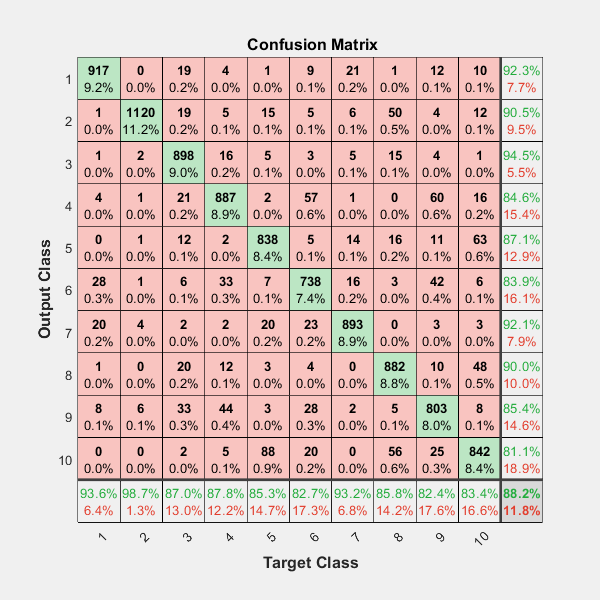

Overall precision: 88.18%


%Real Data
class_labels = NearestSubClassCentroidClassifier(train_labels, train_images, test_images, 3);
plotconfusionMatrixManualMNIST(test_images, test_labels, class_labels')

## Nearest Sub-Class Centroid Classifier 5 PCA

%Pca
class_labels = NearestSubClassCentroidClassifier(train_labels, train_pca, test_pca, 5);

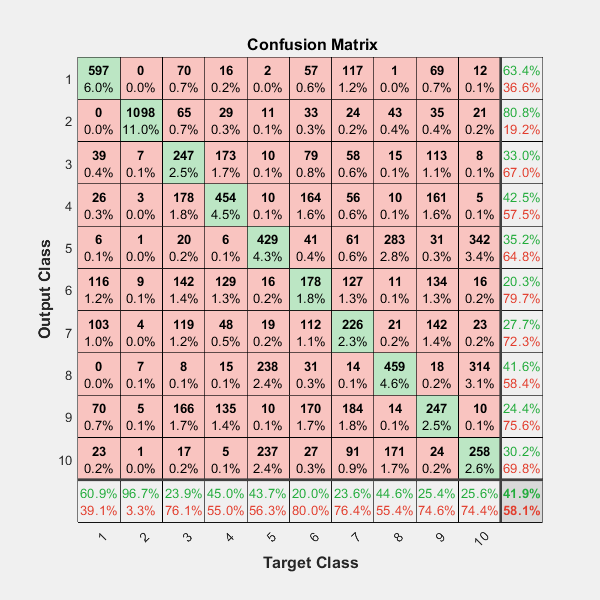

Overall precision: 41.93%


plotconfusionMatrixManualMNIST(test_pca, test_labels, class_labels')

## Nearest Sub-Class Centroid Classifier 5

%Real Data
class_labels = NearestSubClassCentroidClassifier(train_labels, train_images, test_images, 5);

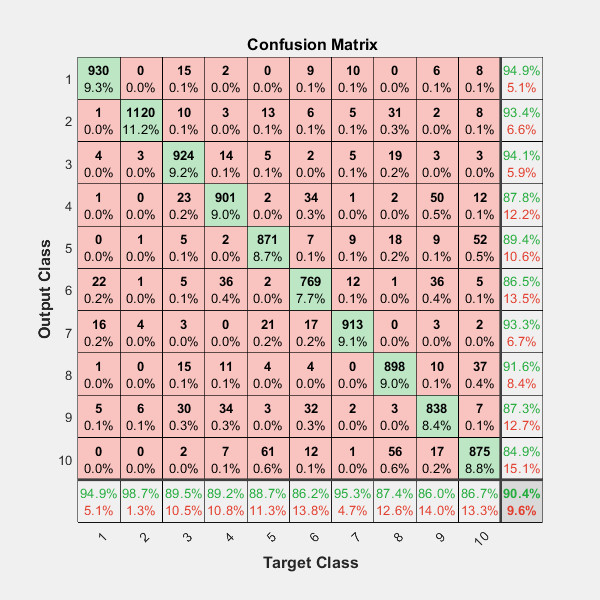

Overall precision: 90.39%


plotconfusionMatrixManualMNIST(test_images, test_labels, class_labels')

## Nearest Neighbor classifier PCA

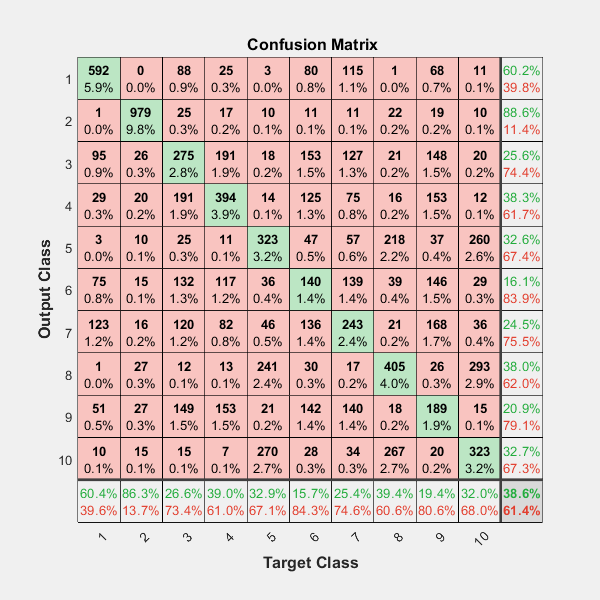

Overall precision: 38.63%


%Pca
class_labels = NearestNeighborClassifier(train_labels, train_pca, test_pca);
plotconfusionMatrixManualMNIST(test_pca, test_labels, class_labels)

## Nearest Neighbor classifier

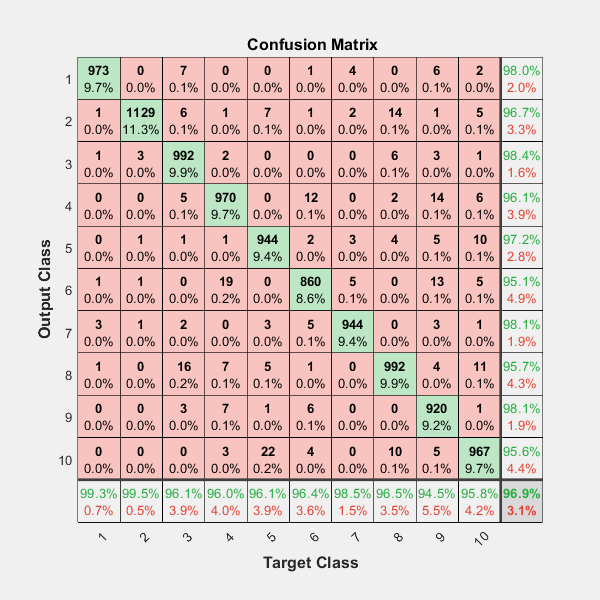

Overall precision: 96.91%


%Real data
class_labels = NearestNeighborClassifier(train_labels, train_images, test_images);
plotconfusionMatrixManualMNIST(test_images, test_labels, class_labels)

## Perceptron with backpropagation PCA

nDOT     = 10^(-3);
max_runs = 600;

result = perceptron_with_back(train_pca,train_labels,nDOT,max_runs)

bincounts =         5923        6742        5958        6131        5842        5421        5918        6265        5851        5949


result =  -359.2890    0.8940  -44.5520  -45.3670  -28.9250  -31.1820  -48.5990  -22.6510  -44.1280  -32.1230
    1.1294   23.8632    4.0255   22.3541  -20.5899    3.0369   21.9451  -12.5246   -0.3947    4.0527
   42.4111  -80.9825  -49.8554    9.3143    7.5514   -1.7157  -71.1062  -23.7302  -73.0165  -32.1603


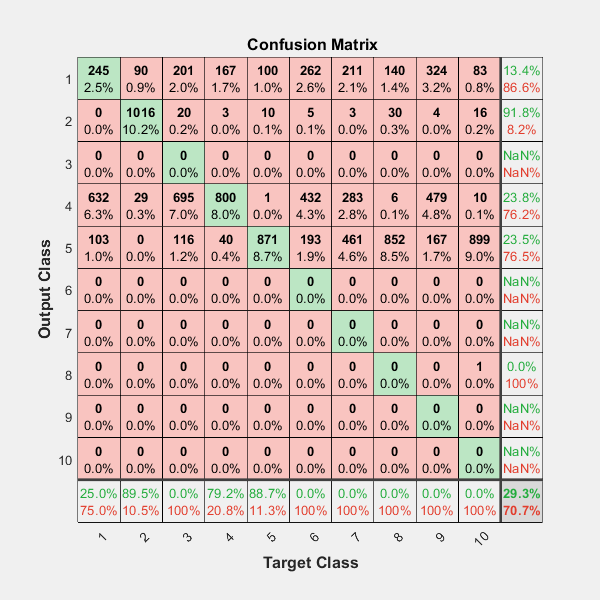

Overall accuracy: 84.306%



plots_perceptronForMNISTPcaVersion(test_pca,test_labels,result);

## Perceptron with backpropagation

%Real data
result = perceptron_with_back(train_pca,train_labels,nDOT,max_runs)

plots_perceptronForMNIST(test_images,test_labels,result)

## Perceptron LMS PCA

w = Perceptron_LMS(train_labels, train_pca)

w =    -1.2569   -0.3519   -0.8518   -0.8361   -0.7689   -0.8651   -0.8851   -0.6564   -0.8064   -0.7214
    0.0352    0.1005    0.0640    0.0991   -0.1179    0.0261   -0.0003   -0.1271    0.0385   -0.1181
    0.1516   -0.1445    0.0153    0.0112   -0.0093    0.0147    0.0276   -0.0421   -0.0005   -0.0241


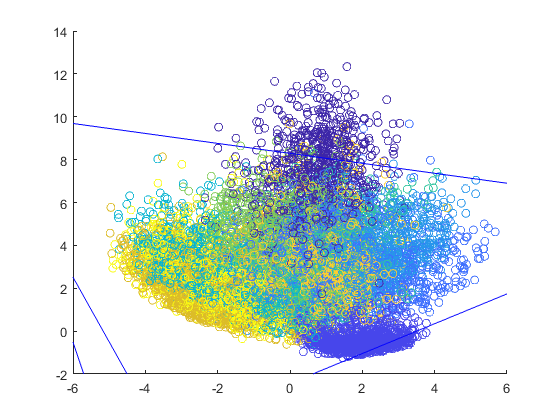


figure
scatter(test_pca(1,:),test_pca(2,:),[],test_labels)
hold on
for i = 1:size(w,2)
    plotpc(w(2:end,i)',w(1,i));
end
hold off

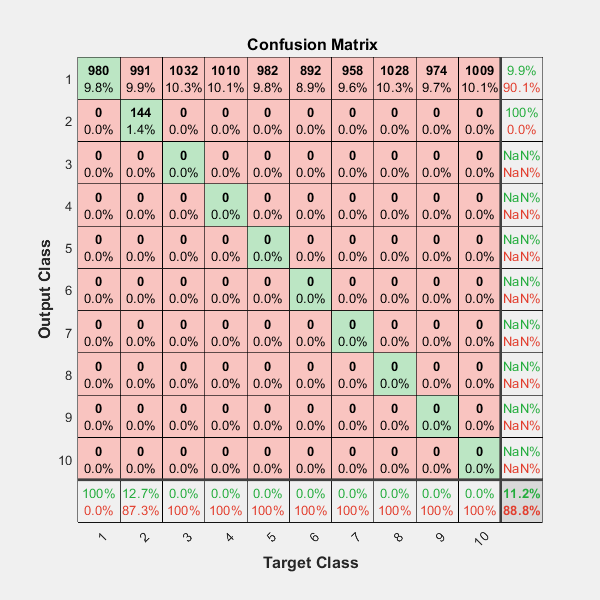

Overall accuracy: 90.393%



plots_perceptronForMNISTPcaVersion(test_pca,test_labels,w);

## Perceptron LMS

w = Perceptron_LMS(train_labels, train_images)

w =    -0.6844   -0.5173   -0.9003   -0.9598   -0.5824   -0.6228   -0.8610   -0.7169   -1.2460   -0.9090
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
  -30.3232   10.1744    9.1996  -13.5964   12.4488    0.3666   -0.7510    4.1085   -1.3055    9.6781
    7.7375   -2.0091   -2.3198    2.3146   -2.5973    0.2275    0.1750   -2.0915    0.2

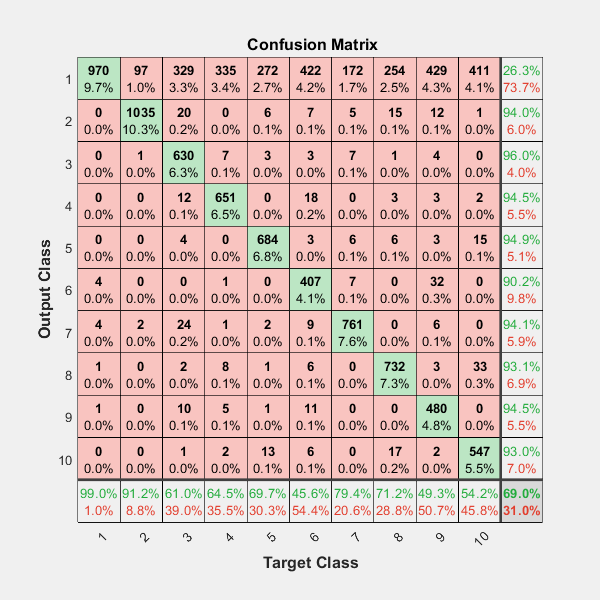

Overall accuracy: 96.348%


plots_perceptronForMNIST(test_images,test_labels,w)